## **SIMULATION DATA**

% Load parameters
clear all
clc;

load('parameters.mat');

simul.select1 = 1;      % takes values in {1, 2} = {deg, rpm} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.stair_gain = 1;   % takes values in {-1, 1}
simul.ramp_gain = 1;    % takes values in [0,1]
simul.stepdeg = 0;      % sets the step amplitude of the deg step

warning('off','all')

#### **[1.1] Positive stair simulation**

% Chose the correct simulation reference
simul.select1 = 2;
simul.select2 = 2;
simul.stair_gain = 1;

positive_stair.wref = timeseries(wref.signals.values, wref.time);
positive_stair.wl_meas = timeseries(wl_meas.signals.values, wref.time);
positive_stair.thref = timeseries(thref.signals.values, wref.time);
positive_stair.thl_meas = timeseries(thl_meas.signals.values, wref.time);
positive_stair.ia = timeseries(ia.signals.values, wref.time);
positive_stair.u = timeseries(u.signals.values, wref.time);
positive_stair.e = timeseries(e.signals.values, wref.time);
save('positive_stair.mat','positive_stair')

%positive_stair = sim('lab_test','StartTime','0','StopTime','45');
clear wref wl_meas thref thl_meas ia u e

#### **[1.2] Negative stair simulation**

% Chose the correct simulation reference
simul.select1 = 2;
simul.select2 = 2;
simul.stair_gain = -1;

negative_stair.wref = timeseries(wref.signals.values, wref.time);
negative_stair.wl_meas = timeseries(wl_meas.signals.values, wref.time);
negative_stair.thref = timeseries(thref.signals.values, wref.time);
negative_stair.thl_meas = timeseries(thl_meas.signals.values, wref.time);
negative_stair.ia = timeseries(ia.signals.values, wref.time);
negative_stair.u = timeseries(u.signals.values, wref.time);
negative_stair.e = timeseries(e.signals.values, wref.time);
save('negative_stair.mat','negative_stair')
clear wref wl_meas thref thl_meas ia u e

save('negative_stair.mat','negative_stair')

#### **[1.3] FRICTION ESTIMATION**

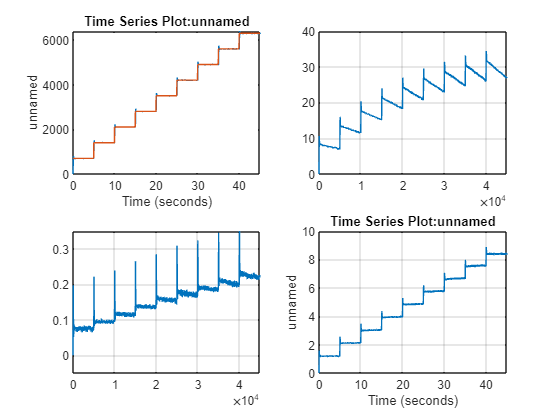

      Beq: 1.9583e-06
    tausf: 0.0062



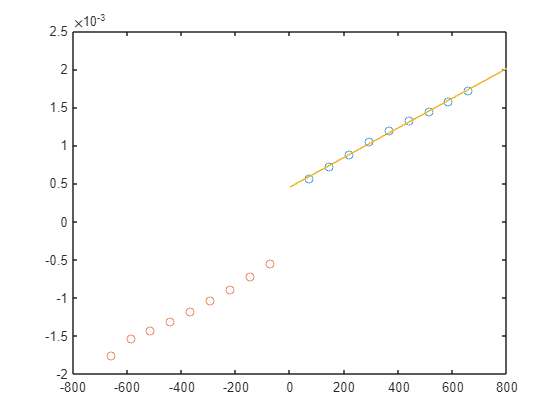

   1.8918e-06   2.0247e-06
   5.8348e-03   6.6013e-03



run('Friction_estimation.mlx')

Initialization of all parameters that has been deleted

simul.select1 = 1;      % takes values in {1, 2} = {deg, rpm} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.stair_gain = 1;   % takes values in {-1, 1}
simul.ramp_gain = 1;    % takes values in [0,1]
simul.stepdeg = 0;      % sets the step amplitude of the deg step

warning('off','all')

#### [2.1] Inertia estimation

simul.select1 = 2;      % rpm reference
simul.select2 = 3;      % stair reference

% Generate a vector that contains the estimate of Jeq for each run
% The final values correspond to its mean
% Set the numbers of experiments
simul.Nexp = 2;
Jeq.vals = zeros(simul.Nexp);
simul.ramp_gain = 0.6;

triang_ref.wref = timeseries(wref.signals.values, wref.time);
triang_ref.wl_meas = timeseries(wl_meas.signals.values, wref.time);
triang_ref.thref = timeseries(thref.signals.values, wref.time);
triang_ref.thl_meas = timeseries(thl_meas.signals.values, wref.time);
triang_ref.ia = timeseries(ia.signals.values, wref.time);
triang_ref.u = timeseries(u.signals.values, wref.time);
triang_ref.e = timeseries(e.signals.values, wref.time);
save('triang_ref.mat','triang_ref')
clear wref wl_meas thref thl_meas ia u e

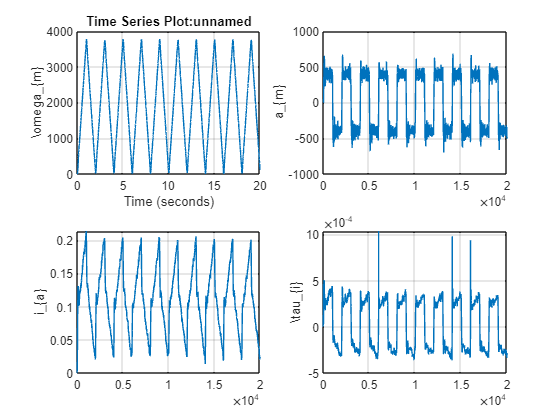

run("Inertia_estimation.mlx");

We run different simulation varing the ramp amplitude

Found algebraic loop containing: 
lab0_sim_deg/PID/FIX  (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)
lab0_sim_deg/Quanser SRV-02 + NI DAQ/Quanser SRV-02 (discontinuity)
lab0_sim_deg/Quanser SR

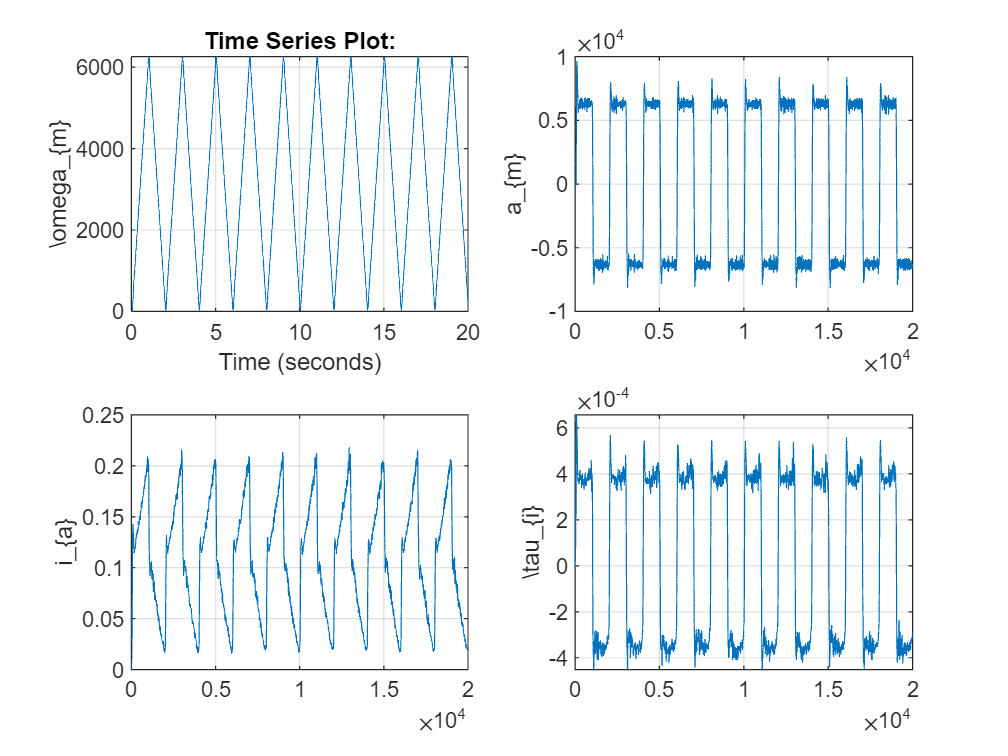

Jeq = struct with fields:
    vals: [0 0 0 0 0 0 0 0 0 9.3936e-12]


Invalid setting in 'lab0_sim_deg/Reference generator/Constant' for parameter 'Value'.

Caused by:
    Error using simulation_data
    Error evaluating parameter 'Value' in 'lab0_sim_deg/Reference generator/Constant'
        Error using simulation_data
        Unrecognized field name "select2".

simul.ramp_gain = 1;

for i = 1: simul.Nexp
    clear triang_ref
    clear est
    simul.ramp_gain = 1/i;
    triang_ref = sim('lab_test','StartTime','0','StopTime','20');
    run("Inertia_estimation.mlx");
    load("Je.mat");
    Jeq.vals(i) = est.Je
end


Jf = mean(Jeq.vals)